# EE482 LAB 2

Tylor Cooks, 026538081

Defining given parameters

n = 1000; % number of samples
%s_ij = [1 .5; -1 1]; % signal projected onto basis function
s_ij = [-5 0; 5 0]

s_ij =     -5     0
     5     0


% E1 Energy signal 1 
% E2 Energy power signal 2
E1 = 13.97;
E2 = 13.97;
data = randi([0,1],[1,n]); %random integer generator between 0-1

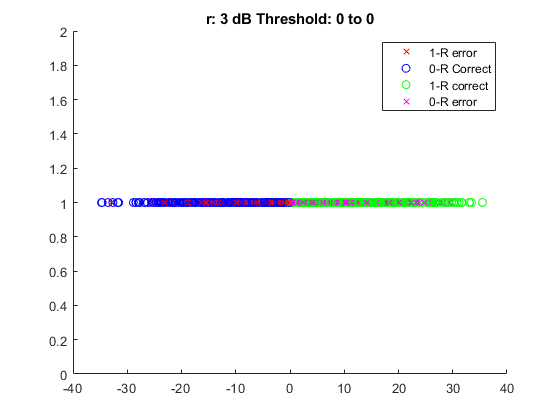

Error_percentage = 36.2000

Percentage of Transmission Request for threshold [0.0 to 0.0], SNR = 3 : 0.0% 


Probability error for threshold [0.0 to 0.0], SNR = 3 : 34.46% 


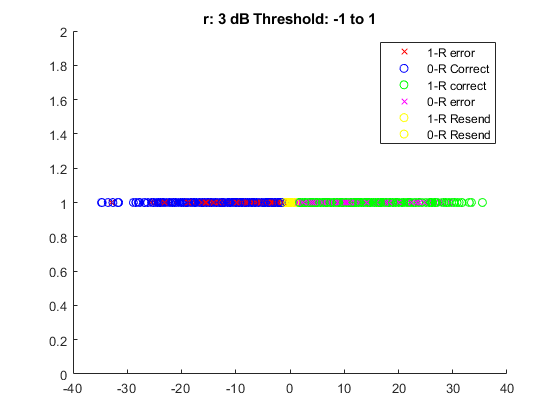

Error_percentage = 32.4000

Percentage of Transmission Request for threshold [-1.0 to 1.0], SNR = 3 : 6.4% 


Probability error for threshold [-1.0 to 1.0], SNR = 3 : 37.45% 


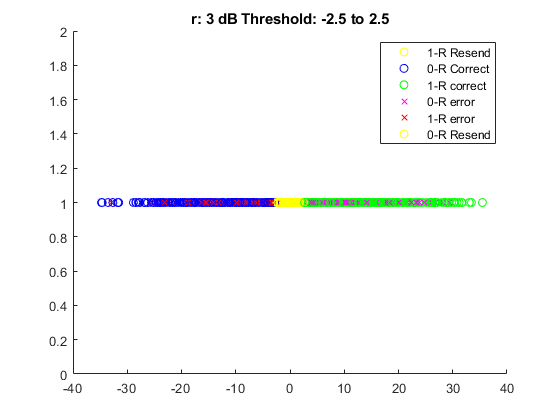

Error_percentage = 28.1000

Percentage of Transmission Request for threshold [-2.5 to 2.5], SNR = 3 : 15.3% 


Probability error for threshold [-2.5 to 2.5], SNR = 3 : 42.08% 


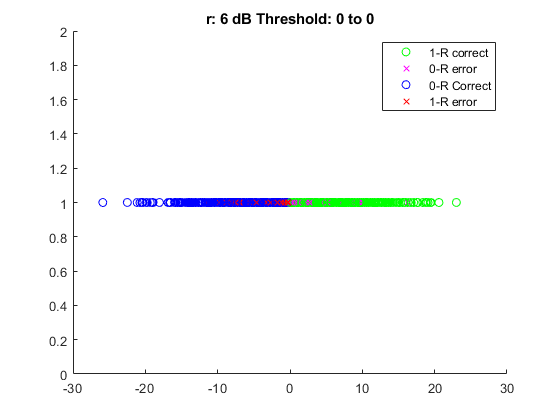

Error_percentage = 20.8000

Percentage of Transmission Request for threshold [0.0 to 0.0], SNR = 6 : 0.0% 


Probability error for threshold [0.0 to 0.0], SNR = 6 : 21.25% 


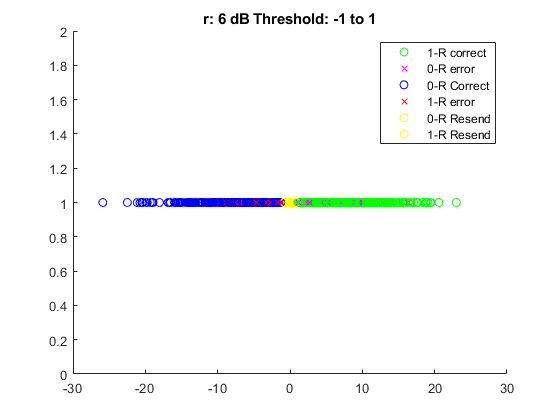

Error_percentage = 16.3000

Percentage of Transmission Request for threshold [-1.0 to 1.0], SNR = 6 : 9.5% 


Probability error for threshold [-1.0 to 1.0], SNR = 6 : 26.16% 


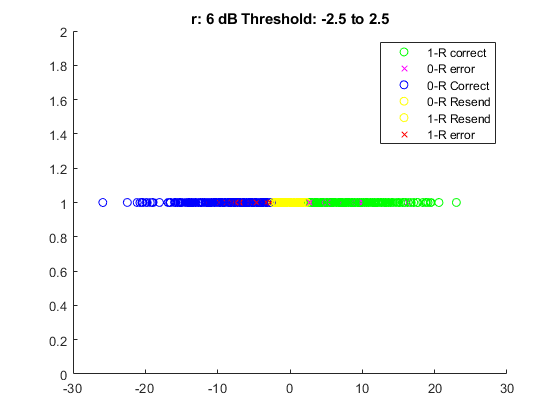

Error_percentage = 11

Percentage of Transmission Request for threshold [-2.5 to 2.5], SNR = 6 : 24.8% 


Probability error for threshold [-2.5 to 2.5], SNR = 6 : 34.50% 


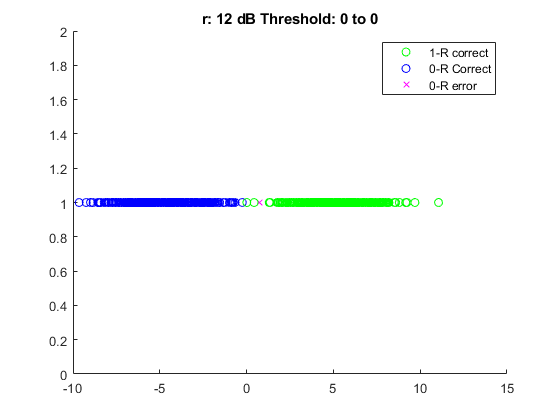

Error_percentage = 0.1000

Percentage of Transmission Request for threshold [0.0 to 0.0], SNR = 12 : 0.0% 


Probability error for threshold [0.0 to 0.0], SNR = 12 : 0.07% 


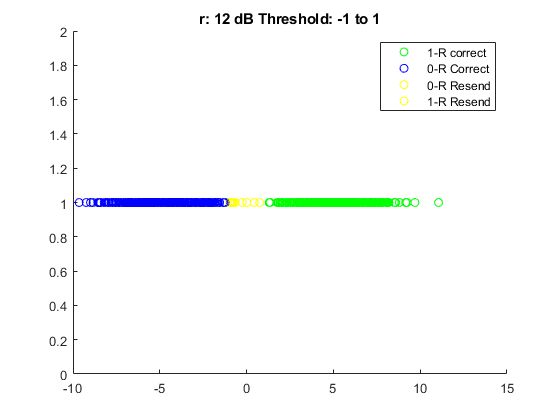

Error_percentage = 0

Percentage of Transmission Request for threshold [-1.0 to 1.0], SNR = 12 : 1.0% 


Probability error for threshold [-1.0 to 1.0], SNR = 12 : 0.55% 


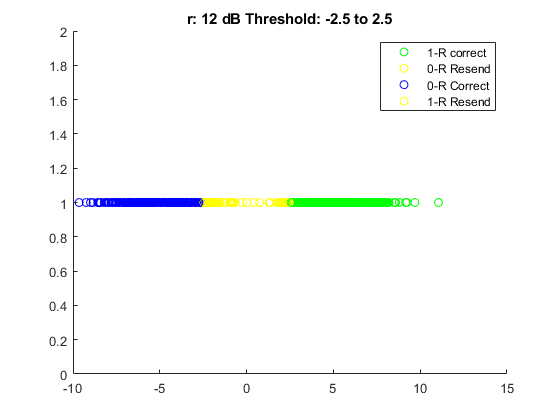

Error_percentage = 0

Percentage of Transmission Request for threshold [-2.5 to 2.5], SNR = 12 : 7.9% 


Probability error for threshold [-2.5 to 2.5], SNR = 12 : 5.61% 


SNRs = [3 6 12];
i = 1;
Tl = [0 -1 -2.5];

Tu = [0 1 2.5];
t = length(Tl);
for snr_db = SNRs
    sigma1 = 10^((E1-snr_db)/10);
    sigma2 = 10^((E2-snr_db)/10);
    
    % Additive white gaussian noise 
    w1 = normrnd(0,sigma1,1,n);
    w2 = normrnd(0,sigma2,1,n);
 
    r11 = (s_ij(1,1)+ w1);
    r21 = (s_ij(2,1)+ w1); 
    
    %if the intended signal is 1, use this
    d1 = (r21 - s_ij(1,1)).^2  >=...
         (r21 - s_ij(2,1)).^2 ;
     
    %if the intended signal is 0, use this
    d0 = (r11 - s_ij(1,1)).^2  >=...
         (r11 - s_ij(2,1)).^2 ;
    
    
    r = zeros(1,n);
       
    % Part 1 [Comparison of the new decision rule to the conventional one]
    % Part 2 [Effects of SNRs on the system performance]
   for t = 1:length(Tl)
    count = 0;
    count1 = 0;
    figure()
    for v = 1:n
      
      if data(v) == 1
        r(1,v) = (r21(v));
        if (Tl(t) < r(v)) && (r(v) < Tu(t))
           scatter(r(v),1,'y','DisplayName','1-R Resend')
           count = count+1;
        elseif d1(v) == data(v)
           scatter(r(v),1,'g','DisplayName','1-R correct')
        else
           scatter(r(v),1,'xr','DisplayName','1-R error')
           count1 = count1+1;
        end
      else  
        r(1,v) = (r11(v));
        if (Tl(t) < r(v)) && (r(v) < Tu(t))
            scatter(r(v),1,'y','DisplayName','0-R Resend')
            count = count+1;
        elseif d0(v) == data(v)
            scatter(r(v),1,'b','DisplayName','0-R Correct')
        else 
            scatter(r(v),1,'xm','DisplayName','0-R error')
            count1 = count1+1;
        end
      end
      hold on
    end
    legend(legendUnq());
    title(['r: ', num2str(SNRs(i)), ' dB ', 'Threshold: ',num2str(Tl(t)),' to ', num2str(Tu(t))]);
    hold off
    %compare probability error with actual error percentage
    Error_percentage = (count1/n) * 100
    Thresh_percentage = (count/n)*100;
    x1 = (Tl(t) - s_ij(1,1))/sigma1;
    x2 = (-(Tu(t) - s_ij(2,1))/sigma2);
    Perror = (.5*qfunc(x1) +.5*qfunc(x2))*100;
    fprintf('Percentage of Transmission Request for threshold [%.1f to %.1f], SNR = %d : %.1f%% \n',Tl(t),Tu(t),SNRs(i),Thresh_percentage);
    fprintf('Probability error for threshold [%.1f to %.1f], SNR = %d : %.2f%% \n',Tl(t),Tu(t),SNRs(i),Perror);
   end 


i = i+1;
end

**Part 3 [Discussion]**

    For this project, the optimum reciever included a condition where the threshold boundary, lower and upper bound respectively, iterated between [0 0], [-1 1], and [-2.5 2.5] for SNRs [3 6 12]. For the analysis of threshold boundary for SNRs [3 6] dB, the probability error actually increased from when the threshold was at 0, when the just the decision rule was implemented. This result is to be expected because of the low SNR the noise power sends the bits farther outside than the threshold boundries, while the correct bits received get counted in the threshold boundries. For SNR = 12dB the best results seem to be when the threshold boundries was limited to [-1 1], this would because through testing, a error would sometimes occur within just those boundries and would be caught for resubmission. However, when the threshold was between [-2.5 2.5], a significant amount of correct recieved bits would be caught within the threshold, thus increasing the probability error erronously. 

    In conclusion, having an lower and upper threshold boundries, seem to be most valueable when the SNR is higher, errors seem to happen at a higher frequency towards the center where the threshold boundries are likely to be,  catching stray errors centered within the boundries. In this case, when the SNR = 12dB with the threshold boundries between [-1 1] has the best results. In contrast, at lower SNRs, not only do the threshold boundries incorrectly resubmit bits for retransmission that were correct, it also misses errors that were sent outside those boundries, which will have a higher likelihood of happening at lower SNRs. 